clear;

% Load dataset
datasetName = "dataset16";
files = metadata.selectPreset(metadata.collect('DataSet/Faulty bearing'), datasetName);
sigTable = preprocess.buildSignalTable(files, 1, 0, @io.readCurrent, @io.readVibro);

Error using vertcat
Names of fields in structure arrays being concatenated do not match. Concatenation of structure arrays requires that these
arrays have the same set of fields.

Error in preprocess.buildSignalTable (line 63)
            allEntries = [allEntries; entry]; %#ok<AGROW>

pipeline_opt = struct();
pipeline_opt.exclude = ["Mean_A", ...
                        "Mean_B", ...
                        "Std_A", ...
                        "Std_B", ...
                        "DominantFreq_A", ...
                        "DominantFreq_B", ...
                        "DominantFreq_P", ...
                        "RMS_A", ... // corr with RMS_Vector_Mag
                        "RMS_B", ... // corr with RMS_Vector_Mag
                        "RMS_VectorMag", ... // corr with RMS_P
                        "SpecEnergy_A", ... // corr with RMS_P
                        "SpecEnergy_B", ... // corr with RMS_P
                        "SpecEnergy_P", ... // corr with RMS_P
                        "Mean_P", ... // corr with RMS_P,
                        "Skew_P", ... // corr with Curt_P,
                        "Ellipse_A", ... // corr with RMS_P
                        "Ellipse_B", ... // corr with RMS_P
                        "Entropy_P", ... // corr with Centroid_P
                        ];
pipeline_opt = struct();
[X, Y, featureTbl, featureNames] = features.pipeline(files, pipeline_opt);

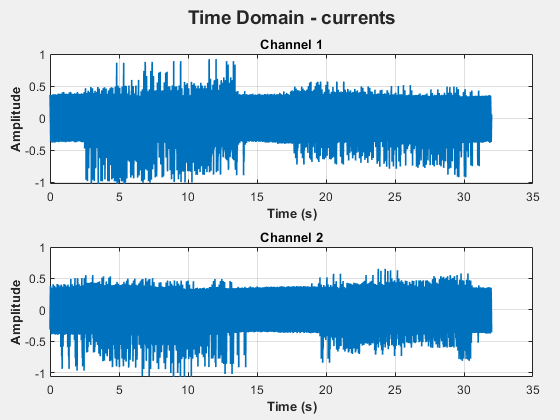

sigRows = preprocess.findRowsByFilePath(sigTable, files.FilePath(7,:));
opts.signalType = 'currents';
fig1 = viz.windowTimeDomain(sigRows, opts);
fig2 = viz.windowFreqDomain(sigRows, opts);
% Show or save
set(fig1, 'Visible', 'on');

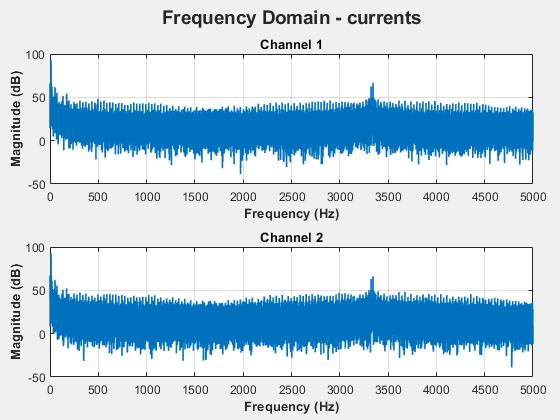

set(fig2, 'Visible', 'on');

clear opts

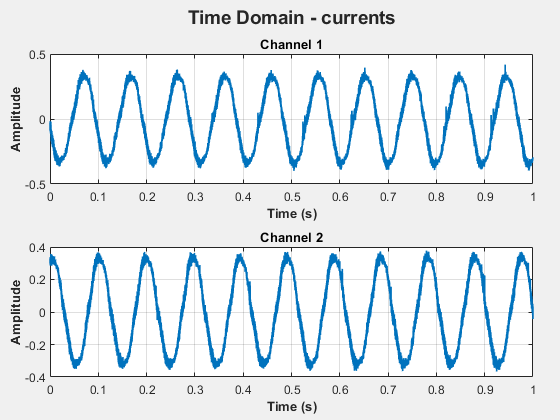

row = sigTable(225,:);
opts.signalType = 'currents';
fig1 = viz.windowTimeDomain(row, opts);
fig2 = viz.windowFreqDomain(row, opts);
% Show or save
set(fig1, 'Visible', 'on');

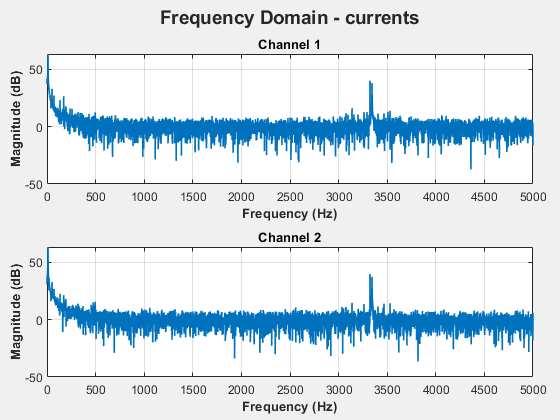

set(fig2, 'Visible', 'on');

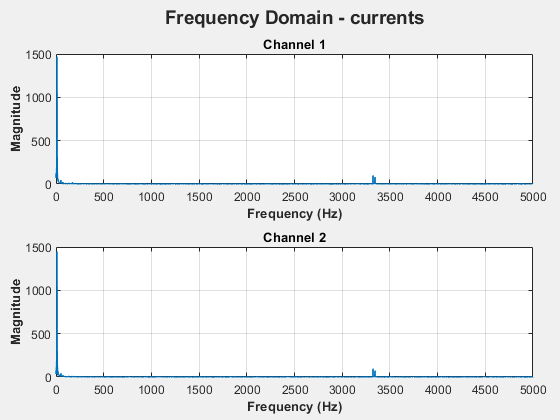

opts.logScale = false;
fig3 = viz.windowFreqDomain(row, opts);
set(fig3, 'Visible', 'on');

clear opts

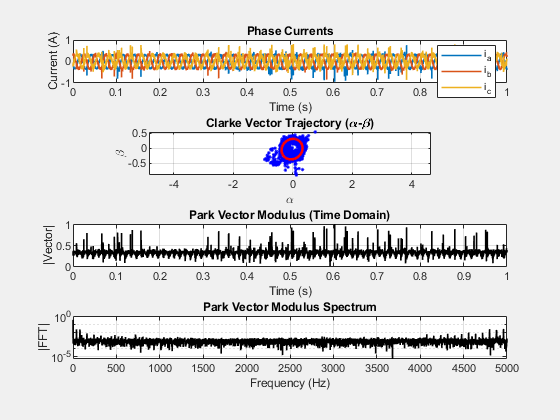


fig4 = viz.parkEllipse(sigTable(530,:));

set(fig4, 'Visible', 'on');


pdf_filename = 'AllParkEllipseFigures.pdf';
if exist(pdf_filename, 'file'), delete(pdf_filename); end

for k = 1:height(sigTable)
    fig = viz.parkEllipse(sigTable(k,:));
    set(fig, 'Visible', 'off'); % Keep invisible for batch

    % Extract metadata fields for labeling
    FilePath     = sigTable.meta(k,:).FilePath;
    timeInterval = sigTable.timeInterval(k,:); % [start, end] as e.g. [0 0.9999]
    
    % Format label string
    labelStr = sprintf('%s\nTime interval: %.3fs - %.3fs', ...
        string(FilePath), timeInterval(1), timeInterval(2));
    
    % Add label as a super-title (sgtitle)
    sgtitle(fig, labelStr, 'FontSize', 10, 'Interpreter', 'none');

    % Export to PDF, appending to the file
    exportgraphics(fig, pdf_filename, 'Append', true);

    close(fig);
end

disp(['All figures with labels saved to ', pdf_filename]);


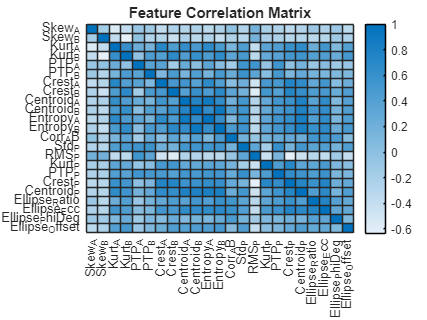

% Features Correlation Check
featureCorrMatrix = corr(X);

figure;
heatmap(featureNames, ...
    featureNames, featureCorrMatrix);
title('Feature Correlation Matrix');

% Output PDF file
outputPDF = 'all_features_current.pdf';

% Delete existing file if already there
if isfile(outputPDF)
    delete(outputPDF);
end

for i = 1:numel(featureNames)
    fname = featureNames{i};

    figScatter = viz.featureScatter(featureTbl, Y, fname);
    exportgraphics(figScatter, outputPDF, 'Append', true);
    close(figScatter);

    % --- Boxplot ---
    figBox = viz.featureBoxplot(featureTbl, Y, fname);
    exportgraphics(figBox, outputPDF, 'Append', true);
    close(figBox);

    % --- PDF plot ---
    figPDF = viz.featurePDF(featureTbl, Y, fname);
    exportgraphics(figPDF, outputPDF, 'Append', true);
    close(figPDF);
end

disp(['All plots saved to: ', outputPDF]);

All plots saved to: all_features_current.pdf


frequencies = {'10hz', '20hz', '30hz', '40hz'};

labelOrders = {["frequency converter №2", "serviceable bearing"], ...
               ["frequency converter №2", "misalignment"]};

rows = [];
row = 1;
rsSignals = {}; % For storing residual signals

for f = 1:numel(frequencies)
    freq = frequencies{f};
    freqTbl = features.select(featureTbl, 'Frequency', freq);

    for i = 1:numel(featureNames)
        for j = 1:numel(labelOrders)
            if ~isempty(freqTbl)
                monoScore = metrics.featureMonotonicity(freqTbl, featureNames{i}, labelOrders{j});
                corrScore = metrics.featureCorr(freqTbl, featureNames{i}, labelOrders{j});
                [robustScore, rs, trend] = metrics.featureRobustness(freqTbl, featureNames{i}, labelOrders{j});
            else
                monoScore = NaN;
                corrScore = NaN;
                robustScore = NaN;
                rs = [];
            end

            rows(row).Frequency     = freq;
            rows(row).FeatureName   = featureNames{i};
            rows(row).LabelOrder    = strjoin(labelOrders{j}, ', ');
            rows(row).MonoScore     = monoScore;
            rows(row).CorrScore     = corrScore;
            rows(row).RobustScore   = robustScore;

            % Save rs for later plotting (optional)
            rsSignals{row,1} = rs;
            trendSignals{row,1} = trend;
            row = row + 1;
        end
    end
end

results = struct2table(rows);

pdfFileName = 'RsSignals.pdf';

% Suppose you stored trend and rs in arrays like: rsSignals, trendSignals
for k = 1:height(results)
    rs = rsSignals{k};
    trend = trendSignals{k};
    if isempty(rs), continue; end

    figure('Visible','off');
    hold on;
    plot(trend + rs, 'b', 'LineWidth', 1.2); % original signal
    plot(trend, 'r--', 'LineWidth', 1.5);    % trend
    plot(rs, 'k:', 'LineWidth', 1);          % residual
    hold off;
    legend('Original','Trend','Residual');
    grid on;
    title(sprintf('Trend & Residual: %s | %s | %s', ...
        results.Frequency{k}, results.FeatureName{k}, results.LabelOrder{k}));
    xlabel('Index');
    ylabel('Value');

    % Export to PDF (append mode)
    if k == 1
        exportgraphics(gca, pdfFileName, 'ContentType', 'vector', 'Append', false);
    else
        exportgraphics(gca, pdfFileName, 'ContentType', 'vector', 'Append', true);
    end

    close(gcf);
end